k = 32

k = 32

m = 8

m = 8

c = 20

c = 20


wn = sqrt(k/m)

wn = 2


z = c/(2*m*wn)

z = 0.6250


wd = wn*sqrt(1-z^2)

wd = 1.5612


syms psi C_s f(t) t ff(t)
f(t) = C_s*exp(-z*wn*t)*(sin(wd*t+psi)) %% Funktionen fra tavlen

$$f(t) = C_{s}\,{\mathrm{e}}^{-\frac{5\,t}{4}}\,\sin\left(\psi +\frac{\sqrt{39}\,t}{4}\right)$$

ff(t) = diff(f(t), t) %% Den differentierede

$$ff(t) = \frac{\sqrt{39}\,C_{s}\,{\mathrm{e}}^{-\frac{5\,t}{4}}\,\cos\left(\psi +\frac{\sqrt{39}\,t}{4}\right)}{4}-\frac{5\,C_{s}\,{\mathrm{e}}^{-\frac{5\,t}{4}}\,\sin\left(\psi +\frac{\sqrt{39}\,t}{4}\right)}{4}$$

x = [f(0) == 0.2, ff(0) == 0] %% sættes op i et arrat så der kan solves for de 2 ukændte. start værdiger t = 0 x = 0.2 osv hastighed er også 0 når t = 0

$$x = \left(\begin{array}{cc} C_{s}\,\sin\left(\psi \right)=\frac{1}{5} & \frac{\sqrt{39}\,C_{s}\,\cos\left(\psi \right)}{4}-\frac{5\,C_{s}\,\sin\left(\psi \right)}{4}=0 \end{array}\right)$$


S = solve(x, psi, C_s) %Solver for psi og C_s i vores x lignings system

S = struct with fields:
    psi: [2×1 sym]
    C_s: [2×1 sym]


vpa(S.psi, 5) %Vpa

$$ans = \left(\begin{array}{c} -2.2459\\ 0.89566 \end{array}\right)$$

vpa(S.C_s, 5) %Vpa

$$ans = \left(\begin{array}{c} -0.25621\\ 0.25621 \end{array}\right)$$

f(t) = S.C_s(2)*exp(-z*wn*t)*(sin(wd*t+S.psi(2))) % Indsætter vores nye værdiger i funktionenn så vi for en real ligning (2) er for at få det korrekte indeks 

$$f(t) = \frac{8\,\sqrt{39}\,{\mathrm{e}}^{-\frac{5\,t}{4}}\,\sin\left(2\,\mathrm{atan}\left(\frac{\sqrt{39}}{13}\right)+\frac{\sqrt{39}\,t}{4}\right)}{195}$$

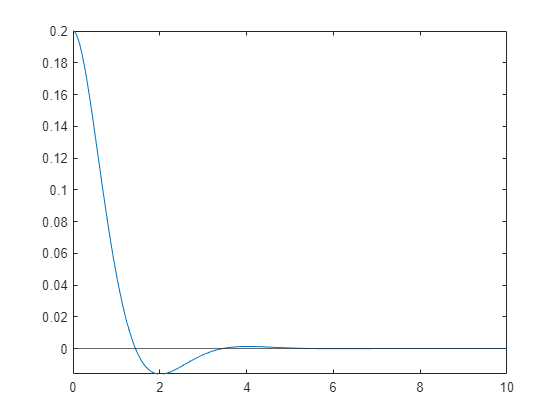

fplot(f(t), [0, 10]) %plot 
xline(0)
yline(0)